Author: Justin Joseph

Group Members: N/a

Course: BME 3053C Computer Applications for BME

Term: Fall 2023

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: justinjoseph@ufl.edu

October 10, 2023

train_data_path = 'M:\Documents\MATLAB\BME3053C\Final Project\MRI Data Set\archive\Training';

% file/lable variables 
filepaths = {};
labels = {};

% have to remove '.' (current directory) and '..' (parent directory)
folds = dir(train_data_path); % 'dir' returns a list of all files and folders in the directory
folds = {folds([folds.isdir]).name}; % filter only directories
folds = folds(~ismember(folds, {'.', '..'})); % remove '.' and '..' from the list

% over whole flder
for fold_index = 1:length(folds)
    fold = folds{fold_index};
    f_path = fullfile(train_data_path, fold);
    
    filelists = dir(f_path);
    filelists = {filelists(~[filelists.isdir]).name}; % only filenames, no directories
    
    for file_index = 1:length(filelists)
        file = filelists{file_index};
        filepaths{end+1, 1} = fullfile(f_path, file);
        labels{end+1, 1} = fold;
    end
end

% Concatenate data paths with labels
train_df = table(filepaths, labels, 'VariableNames', {'filepaths', 'label'});

test_data_path = 'M:\Documents\MATLAB\BME3053C\Final Project\MRI Data Set\archive\Testing';

filepaths = {};
labels = {};

folds = dir(test_data_path); 
folds = {folds([folds.isdir]).name}; 
folds = folds(~ismember(folds, {'.', '..'})); 

for fold_index = 1:length(folds)
    fold = folds{fold_index};
    f_path = fullfile(test_data_path, fold);
    
    filelists = dir(f_path);
    filelists = {filelists(~[filelists.isdir]).name}; 
    
    for file_index = 1:length(filelists)
        file = filelists{file_index};
        filepaths{end+1, 1} = fullfile(f_path, file);
        labels{end+1, 1} = fold;
    end
end

% Concatenate data paths with labels
test_df = table(filepaths, labels, 'VariableNames', {'filepaths', 'label'});

%rng(42); % Set random seed, this was for debuging
cv = cvpartition(height(test_df), 'HoldOut', 0.5); % Create a cvpartition object

% Indices for validation and test sets
valid_indices = cv.training;
test_indices = cv.test;

% Create validation and test tables
valid = test_df(valid_indices, :);
test = test_df(test_indices, :);

img_size = [224, 224]; 
batch_size = 16;

% Convert all grayscale images to RGB, needed for resnet50
convertToRGB = @(x) imresize(convertTo3Channels(imread(x)), img_size);

train_imgDatastore = imageDatastore(train_df.filepaths, 'Labels', categorical(train_df.label), ...
    'ReadFcn', convertToRGB);

valid_imgDatastore = imageDatastore(valid.filepaths, 'Labels', categorical(valid.label), ...
    'ReadFcn', convertToRGB);

test_imgDatastore = imageDatastore(test.filepaths, 'Labels', categorical(test.label), ...
    'ReadFcn', convertToRGB);

% Create an augmented image datastore for training
train_gen = augmentedImageDatastore(img_size, train_imgDatastore);


% For validation and test, since no augmentation is needed, we can use the imageDatastore directly
valid_gen = valid_imgDatastore;
test_gen = test_imgDatastore;

% Get class names
classNames = categories(train_imgDatastore.Labels);

% Read one batch of images and labels
[images, labelStruct] = read(train_gen);


% Print out the type and content of labelStruct to understand its structure
fprintf('Type of labelStruct: %s\n', class(labelStruct));

Type of labelStruct: struct


disp('Content of labelStruct:');

Content of labelStruct:


disp(labelStruct);

    Filename: {128×1 cell}
    FileSize: [128×1 double]
       Label: [128×1 categorical]



**Training**

% Load the pre-trained network
net = resnet50;

% Extract the layer graph
lgraph = layerGraph(net);

% List of layers to replace
layersToReplace = {
    'fc1000'
    'fc1000_softmax'
    'ClassificationLayer_fc1000'
};

% Remove the last three layers
lgraph = removeLayers(lgraph, layersToReplace);

% Define the number of classes
numClasses = numel(categories(train_imgDatastore.Labels));

% Add new layers for the classification
newLayers = [
    fullyConnectedLayer(numClasses, 'Name', 'new_fc', 'WeightLearnRateFactor',10, 'BiasLearnRateFactor',10)
    softmaxLayer('Name', 'new_softmax')
    classificationLayer('Name', 'new_classification')];

% Add new layers to the graph
lgraph = addLayers(lgraph, newLayers);

% Connect the new layer to the network
lgraph = connectLayers(lgraph, 'avg_pool', 'new_fc');

% Check the updated network architecture
figure;
plot(lgraph);

% Augment the training data
augimds = augmentedImageDatastore([224 224], train_imgDatastore);


% Specify training options
opts = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 10, ... 
    'Verbose', true, ...
    'MiniBatchSize', 16, ...
    'Plots', 'training-progress');

% Train the network
[netTransfer, info] = trainNetwork(augimds, lgraph, opts);

**Confusion Matrix **

% Load the trained network 
load('trainedNetwork.mat');

% Predict the labels using the trained network
preds = predict(netTransfer, test_gen);


% Convert predicted labels
[~, y_pred] = max(preds, [], 2);
predictedLabels = classNames(y_pred);

% Get the true labels
trueLabels = test_gen.Labels;

% Print unique true and predicted labels to inspect them
uniqueTrueLabels = unique(trueLabels);
uniquePredictedLabels = unique(predictedLabels);
fprintf('Unique true labels:\n');

Unique true labels:


disp(uniqueTrueLabels);

     glioma 
     meningioma 
     notumor 
     pituitary 



fprintf('Unique predicted labels:\n');

Unique predicted labels:


disp(uniquePredictedLabels);

    {'glioma'    }
    {'meningioma'}
    {'notumor'   }
    {'pituitary' }



predictedLabelsCat = categorical(predictedLabels);
% Generate the confusion matrix
cm = confusionmat(trueLabels, predictedLabelsCat);

% Normalize the confusion matrix
normalized_cm = cm ./ sum(cm, 2);

% Plotting the confusion matrix using heatmap
figure;
h = heatmap(classNames, classNames, normalized_cm, ...
    'ColorbarVisible', 'on', ...
    'CellLabelColor', 'auto', ...
    'CellLabelFormat', '%.2f');

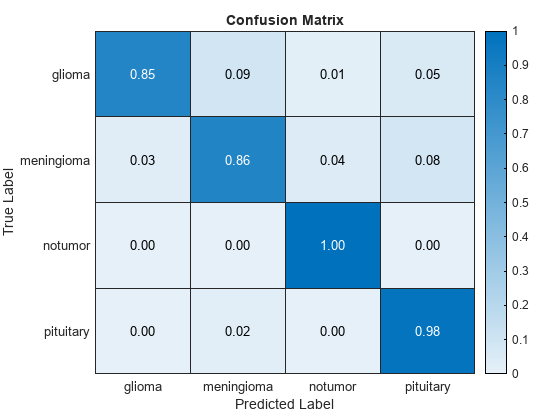


title('Confusion Matrix');
xlabel('Predicted Label');
ylabel('True Label');

**Batch Predicting Images**

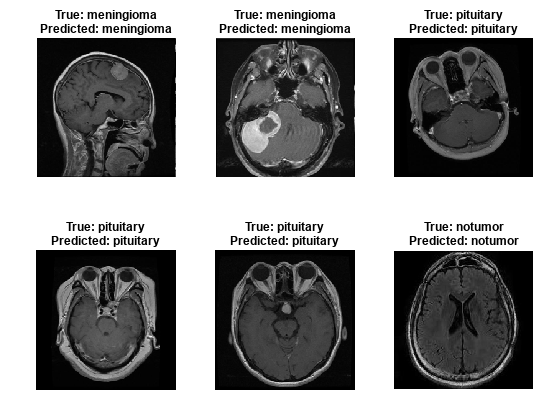

% Load the trained network 
load('trainedNetwork.mat');

% Number of images to predict and display
numImagesToDisplay = 6;

% Generate random indices to select random images from the test dataset
totalNumImages = numel(test_imgDatastore.Files);
randIndices = randperm(totalNumImages, numImagesToDisplay);

% Read the specified number of images at random indices
imgs = cell(numImagesToDisplay, 1);
trueLabels = cell(numImagesToDisplay, 1);
for i = 1:numImagesToDisplay
    index = randIndices(i);
    [img, info] = readimage(test_imgDatastore, index); % Using random index
    imgs{i} = img;
    trueLabels{i} = char(info.Label); % Convert to character array here
end

% Convert cell arrays to numeric/categorical 
imgs = cat(4, imgs{:}); % Concatenating along the 4th dimension to create an image batch
trueLabels = categorical(trueLabels);

% Predict labels
predictedScores = predict(netTransfer, imgs);
[~, predictedIndices] = max(predictedScores, [], 2);
predictedLabels = classNames(predictedIndices);

% Create a testing figure
figure;
t = tiledlayout('flow', 'Padding', 'compact', 'TileSpacing', 'loose');

% Display the images with true and predicted labels
for i = 1:numImagesToDisplay
    ax = nexttile(t); 
    imshow(imgs(:,:,:,i), 'Parent', ax);
    
    title(ax, {
        char("True: " + string(trueLabels(i))), 
        char("Predicted: " + string(predictedLabels(i)))
    });
end

**Predict specific image**

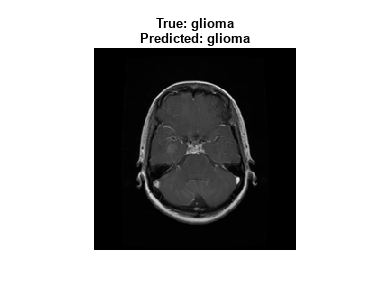

% Load the trained network 
load('trainedNetwork.mat');

% Specify the index of the image in the test_imgDatastore you want to predict
imageIndex = 6; 

% Read the specific image and its label
img = readimage(test_imgDatastore, imageIndex);
trueLabel = test_imgDatastore.Labels(imageIndex);

% Predict the label of the specific image
predictedScores = predict(netTransfer, img);
[~, predictedIndex] = max(predictedScores, [], 2);
predictedLabel = classNames(predictedIndex);

% Display the image with true and predicted labels
figure;
ax = gca;  % get handle to current axes
imshow(img);
tit = title({
    char("True: " + string(trueLabel)), 
    char("Predicted: " + string(predictedLabel))
});

% Adjust axes position to leave space for the title
ax.Position = [ax.Position(1) ax.Position(2) ax.Position(3) ax.Position(4)*0.9];

**Testing the overal accuracy of the model**

[predictedLabels, scores] = classify(netTransfer, test_gen);
trueLabels = test_gen.Labels;
accuracy = sum(predictedLabels == trueLabels) / numel(trueLabels);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 92.52%


**Needed a function to convert images to RGB **

function imgRGB = convertTo3Channels(img)
    if size(img,3) == 1
        imgRGB = cat(3, img, img, img); % Convert grayscale to RGB
    else
        imgRGB = img; % Leave RGB as is
    end
end
